start_point = [2, 3];
num = 2;
objective_func = @Rastrigin;


                           Best        Current           Mean
Iteration   f-count         f(x)         f(x)         temperature
     0          1             13             13            100
    10         11             13        38.3351          56.88
    20         21             13        27.5689        34.0562
    30         31             13        27.7048        20.3907
    40         41             13        20.9183        12.2087
    50         51             13        30.6885        7.30977
    60         61             13        30.0846        4.37663
    70         71        11.0017        11.0017        2.62045
    80         81        4.61092        4.61092        1.56896
    90         91        1.96479        1.96479       0.939395
   100        101        1.96479        1.96479        0.56245
   110        111        1.96479        1.96479        0.33676
   120        121        1.96479        1.96479       0.201631
   130        131        1.70416        1.70416     

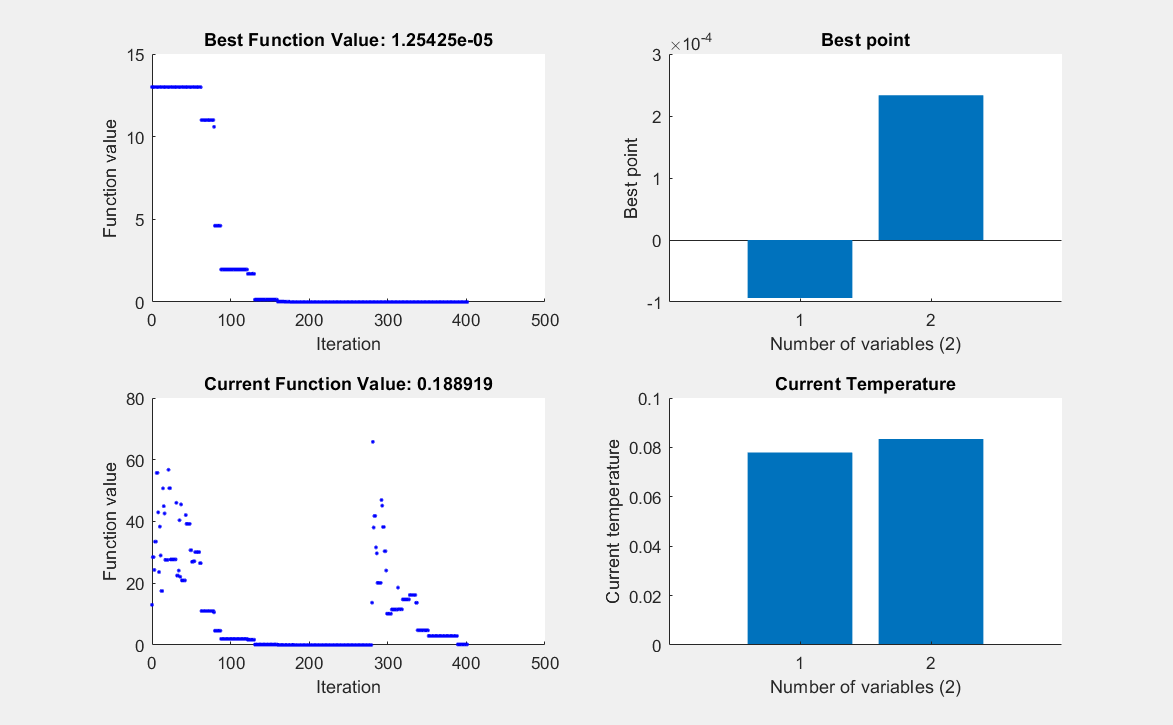

Maximum number of iterations exceeded: increase options.MaxIterations.


% Set nondefault solver options
options = optimoptions("simulannealbnd","MaxIterations",400,"Display","iter",...
    "PlotFcn",["saplotbestf","saplotbestx","saplotf","saplottemperature"]);

% Solve
[solution3,objectiveValue3] = simulannealbnd(@Rastrigin,start_point,...
    repmat(-5.12,size(start_point)),repmat(5.12,size(start_point)),options);


% Clear variables
clearvars options

disp(objectiveValue3);

   1.2542e-05



disp(solution3);

   1.0e-03 *

   -0.0936    0.2334

